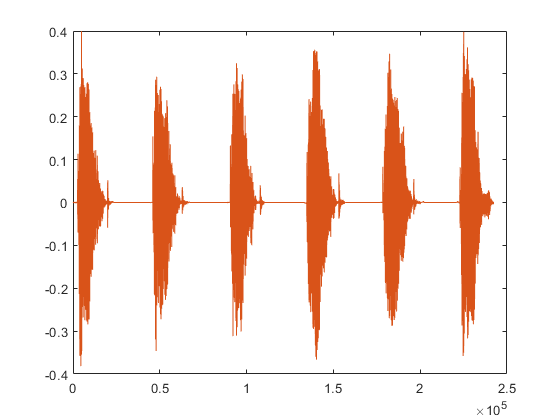

fileName = "Words\Dog.mp3";
[wordData, fs] = audioread(fileName);
duration = (length(wordData)-1)/fs;
plot(wordData)

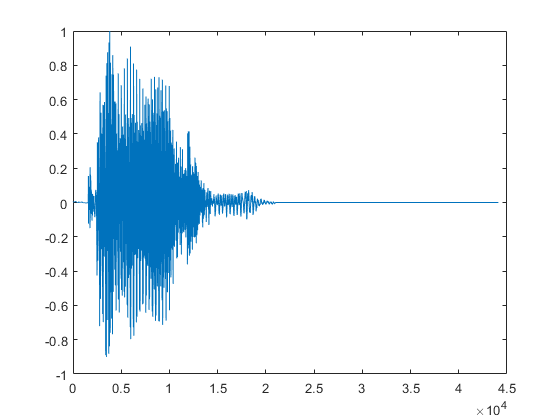

[wordComb] = preProcessor(fileName);
wordLen = length(wordComb);

N = 2^12; %this is the N-parameter for the FFT. Out resolution, etc.
%============================
%    Sean:     We need a way to enfore a specific sample rate. Especially
%    since we resample. Not sure how we do that. Maybe since we know all
%    the samples come in with 44kHz, we can take a specific sample, because
%    a willy-nilly resample will change the meaning of the FFT indexes, so
%    for compatibility we need a standard.
%========

plot(wordComb);

wordResample = resample(wordComb, N, wordLen);
wordReLen = length(wordResample)

wordReLen = 4096

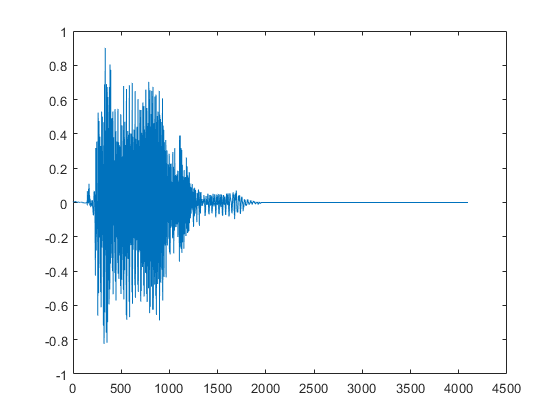


plot(wordResample);